### Tensor reconstructie

Vergelijking tussen verschillende sampling methodes om een tensor te reconstrueren. Figuren geven de relavtieve norm tussen de exacte tensor en de bekomen tensor. 

De gebruikte tensoren zijn:

- Y1: tensor met size: 100x100x100 gegenereerd van een Tucker decompositie met rang 10x10x10

- Y2: tensor met size 100x100x100 waarbij Y2(i,j,k) = 1/(i+j+k)^2

- R: synthetische tensor met size 200x200x100.

R = buildRtensor([200,200,100],4);
sinterval = linspace(0.05,1,3);
methods = ["FSTD","ParCube10","MACH10","ParCube20","MACH20"];
approxReconstructionTest(R,methods,1,sinterval);

# Exacte cluster methodes

Vergelijking tussen verschillende exacte methodes om de tensor R te clusteren. Deze methodes gebruiken alle elementen in de tensor. De methodes worden opgedeeld in 3 groepen. Methodes gebaseerd op: de Tucker decompositie, CP decomposities en andere methodes. 

De methodes worden getest op een R tensor met 4 clusters. 

[R,Rp,expectedClusters] = buildRtensor([200,200,100],4);

## Methodes gebaseerd op een Tucker decompositie

methods = ["Tucker1","Tucker2","Tucker3","Random"];
ExactTest(4,R,R,Rp,methods,'expected',expectedClusters);

## Methodes gebaseerd op de CP decompositie

methods = ["CP1","CP2","Random"];
ExactTest(4,R,R,Rp,methods,'expected',expectedClusters);

## Methodes die niet gebaseerd zijn op een decompositie

methods = ["Venu","SFC","BestMatrix","Random"];
ExactTest(4,R,R,Rp,methods,'expected',expectedClusters);

## Een iets moeilijkere tensor

We gebruiken een iets moeilijkere tensor. We nemen een grootte van 200, 200, 50 en een sigma van 6.

[R,Rp,expectedClusters] = buildRtensor([200,200,75],4,"sigma",5.5);
methods = ["Tucker1","Tucker2","CP1","Venu","SFC","Random"];
Rrange = 5:2:40;
ExactTest(4,R,R,Rp,methods,'expected',expectedClusters,'Rrange',Rrange);

# Cluster methodes gebaseerd op sampling methodes

Vergelijking tussen verschillende sampling methodes om de tensor Yn te clusteren. Deze methodes gebruiken een subset van de elementen. Ook deze methodes worden op dezelfde manier opgedeeld.

### Methodes gebaseerd op de Tucker decompositie

[R,Rp,expectedClusters] = buildRtensor([200,200,100],4);
methods = ["FSTD1","FSTD2","MACH1","MACH2","Random"];
% srange = logspace(-3,-0.5,10);
srange = linspace(0.01,0.51,15);
approxTest(4,R,R,R,methods,'expected',expectedClusters,'sinterval',srange);

#### Methodes gebaseerd op de CP decompositie

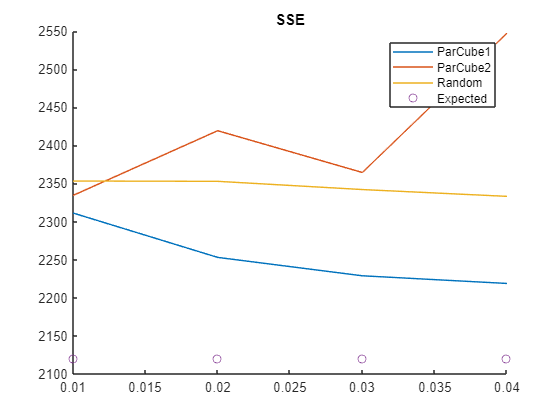

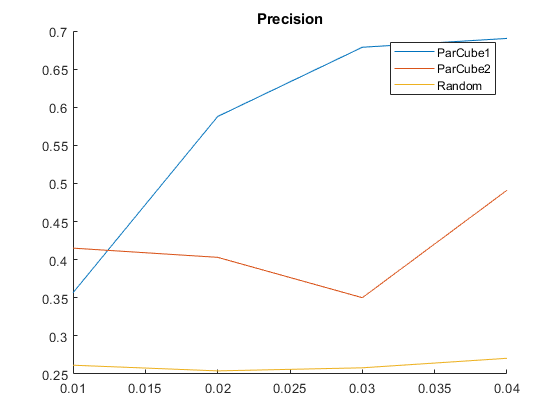

[R,Rp,expectedClusters] = buildRtensor([200,200,100],4);

methods = ["ParCube1","ParCube2","Random"];
srange = linspace(0.01,0.04,4);
approxTest(4,R,R,R,methods,'expected',expectedClusters,'sinterval',srange);

#### Methodes die niet gebaseerd zijn op een decompositie

methods = ["Venu","SOLSFC","Random"];
approxTest(4,R,R,R,methods,'expected',expectedClusters,'sinterval',srange);

## Gebruik moeilijkere tensor

We testen de beste sampling methodes met een moeilijkere tensor met grootte (200,200,50) en mu/sigma = 6/10

% [R,Rp,expectedClusters] = buildRtensor([200,200,75],4,"sigma",5.5);
% methods = ["Venu","SOLSFC","MACH1","Random"];
% srange = linspace(0.01,0.7,15);
% approxTest(4,R,R,Rp,methods,'expected',expectedClusters,'sinterval',srange);

# Verbeteringen methodes

We kunnen de sampling methodes aanpassen om beter aan te sluiten aan de clustering taak. Op deze manier proberen we betere resultaten te halen.

## Benadering vs clustering

Het is natuurlijk om te verwachten dat een beter benadering zal leiden tot een betere clustering. Dit is echter niet altijd waar. Zoals blijkt uit vorige voorbeelden geven de methodes gebaseerd op MACH een beter resultaat dan die op FSTD, terwijl FSTD consistent een betere benadering geeft dan MACH. Het optimaliseren van de benadering zal dus niet rechstreeks leiden tot een betere clustering. 

De sampling methodes zijn echter gemaakt om een zo goed mogelijke benadering te maken. Ze hechten daarom meer belang aan de grootste elementen uit de tensor. Die goed benaderen geeft namelijk een groot verschil in de benaderingfout. voor het clusteren is de exacte waarde van groote waarden misschien minder belangrijk. Dit legt namelijk de focus op elementen die waarschijnlijk niet in dezelfde cluster liggen en op uitschieters. Vooral de FSTD methode doet dit. Daarom belijken we drie aanpassingen aan deze methode.

- FSTDX: kiest willekeurige fibers. 

- FSTDY: kiest de fiber met de grootste relatieve fout.

- FSTDZ: gebruikt een distributie waarbij de kans dat een fiber gekozen wordt evenredig is met de relatieve fout.

% [R,Rp,expectedClusters] = buildRtensor([200,200,75],4,"sigma",5.5);
% methods = ["FSTDX1","FSTDY1","FSTDZ1","FSTD1","Random"];
% srange = linspace(0.01,0.50,15);
% approxTest(4,R,R,R,methods,'expected',expectedClusters,'sinterval',srange);
[R,Rp,expectedClusters] = buildRtensor([200,200,75],4,"sigma",5.5);
methods = ["FSTDX2","FSTDY1","FSTDY2","FSTD1","Random"];
% srange = logspace(-3,-0.5,10);
srange = linspace(0.01,0.50,15);
approxTest(4,R,R,R,methods,'expected',expectedClusters,'sinterval',srange);

Ook de ParCube methode maakt gebruik van een methode die zal focussen op de grootste fibers. ParCubeX kiest willekeurige fibers.

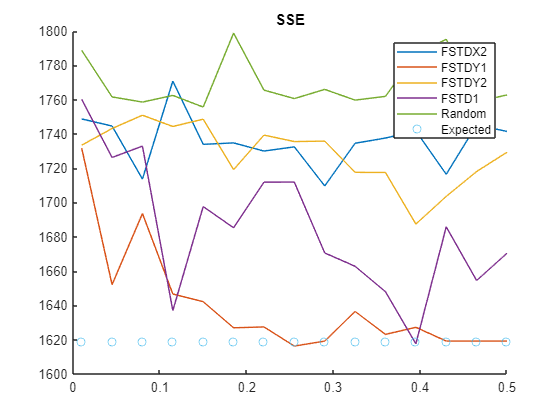

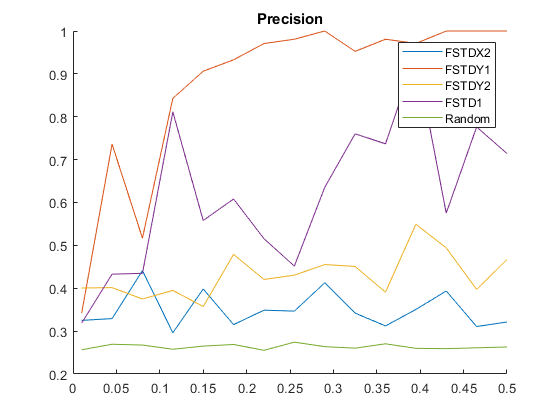

[R,Rp,expectedClusters] = buildRtensor([200,200,100],4,"sigma",5);
methods = ["ParCubeX1","ParCube1","Random"];
% srange = logspace(-3,-0.5,10);
srange = linspace(0.01,0.50,15);
approxTest(4,R,R,R,methods,'expected',expectedClusters,'sinterval',srange);

Net als Venu. We bekijken twee varianten.

- VenuRa: kiest willeukrige fibers.

- VenuSp: kiest fibers die zo gespreid mogleijk zijn in de matrixizatie van de tensor.

[R,Rp,expectedClusters] = buildRtensor([200,200,75],4,"sigma",5.5);
methods = ["Venu","VenuRa","VenuSp","Random"];
% srange = logspace(-3,-0.5,10);
srange = linspace(0.005,0.03,15);
approxTest(4,R,R,R,methods,'expected',expectedClusters,'sinterval',srange);

## Gebruik non-negative factorizatie

In sommige gevallen kunnen we een non-negative beperking opleggen op de factor marices. Dit zorgt ervoor dat alle elementen positief zijn.

Voor MACH kunnen we gebruik maken van een non-negative tucker decompositie.

Use4D=false;
initialize;
% sinterval = logspace(-3,0,15);
sinterval = linspace(0.1,1,10);
methods = ["MACHX20","MACH20"];
approxReconstructionTest(Yn,methods,1,sinterval);

[R,Rp,expectedClusters] = buildRtensor([200,200,100],4,"sigma",5);
methods = ["MACH1","MACHnn1"];
% srange = logspace(-3,-0.5,10);
srange = linspace(0.01,0.50,15);
approxTest(4,R,R,R,methods,'expected',expectedClusters,'sinterval',srange);

Zelfde voor ParCube

Use4D=false;
initialize;
% sinterval = logspace(-3,0,15);
sinterval = linspace(0.1,1,10);
methods = ["ParCube20","ParCubenn20"];
approxReconstructionTest(Yn,methods,1,sinterval);

[R,Rp,expectedClusters] = buildRtensor([200,200,100],4,"sigma",5);
methods = ["ParCube1","ParCubenn1","Random"];
% srange = logspace(-3,-0.5,10);
srange = linspace(0.01,0.50,15);
approxTest(4,R,R,R,methods,'expected',expectedClusters,'sinterval',srange);

We maken een benadering van de eerste factor matrix van de CP decompositie. We gaan de andere factor matrices niet benaderen. We gebruiken de formules om de CP te berekenen met ALS.

[R,Rp,expectedClusters] = buildRtensor([200,200,75],4,"sigma",5.5);
methods = ["MACH1","MACHnn1","ParCube1","ParCubenn1","ParCubennX1","Random"];
% srange = logspace(-3,-0.5,10);
srange = linspace(0.01,0.50,15);
approxTest(4,R,R,R,methods,'expected',expectedClusters,'sinterval',srange);

## Gebruik LMLRA

werkt redelijk goed, maar is extreem traag.

[R,Rp,expectedClusters] = buildRtensor([100,100,50],4,"sigma",5);
methods = ["MACH1","MACHnan1","Venu","Random"];
% srange = logspace(-3,-0.5,10);
srange = linspace(0.1,0.30,10);
approxTest(4,R,R,R,methods,'expected',expectedClusters,'sinterval',srange);

## Gebruik similarity tensor

[R,Rp,expectedClusters] = buildRtensor([200,200,100],4,"sigma",5);
Rs = 1/(1+R);
methods = ["FSTDY1","VenuSp","Random"];
% srange = logspace(-3,-0.5,10);
srange = linspace(0.005,0.1,10);
approxTest(4,{R,Rs},R,Rp,methods,'expected',expectedClusters,'sinterval',srange,'tensorNames',["-Dis","-Sim"]);

[R,Rp,expectedClusters] = buildRtensor([200,200,150],40,"sigma",3);
Rs = 1/(1+R);
methods = ["VenuSp","Random"];
% srange = logspace(-3,-0.5,10);
srange = linspace(0.001,0.01,10);
approxTest(40,{R,Rs},R,Rp,methods,'expected',expectedClusters,'sinterval',srange,'tensorNames',["-Dis","-Sim"]);

## Gebruik Rp

[R,Rp,expectedClusters] = buildRtensor([200,200,100],4,"sigma",5);
methods = ["VenuSp","VenuSpP","FSTDY1","FSTDYP1","MACH1","MACHP1","Random"];
srange = linspace(0.01,0.3,10);
approxTest(4,R,R,Rp,methods,'expected',expectedClusters,'sinterval',srange);

[C,expectedClusters] = buildCTensor([200,200,100],5,5);
methods = ["VenuSp","MACH1","FSTDY1","Random"];
srange = linspace(0.01,0.3,10);
approxTest(5,C,C,[],methods,'expected',expectedClusters,'sinterval',srange);

# Timing van verschillende methodes

## Timing in functie van de samplingrate

R = buildRtensor([200,200,100],5);
srange = 0.01:0.01:0.1;
figure;
timeApproxMethods(["VenuSp","SOLSFC","FSTDY1"],{R},srange,5,3);

## Timing in functie van grootte tensor

Rs = {};
for i=1:4
    i
    Rs{1,i} = buildRtensor([200*i,200*i,200*i],5);
end
figure;
timeApproxMethods(["VenuSp"],Rs,0.1,5,3);

## Timing in functie van het het aantal dimenties. 

We proberen de 

Rs = {};
for n=1:4
    n
    sz = 226^(1/n)*ones(1,n+2);
    sz(1:2) = 20;
    sz = round(sz);
    Rs{1,n} = buildRtensor(sz,5);
end
figure;
timeApproxMethods(["FSTDY1"],Rs,0.1,5,'retries',1);

# Echte datasets

In wat volgt tensten we de verschillende methodes op basis van 3 echte datasets

## Amie dataset

#### Methodes gebaseerd op de Tucker decompositie

Use4D = false;
initialize;
methods = ["FSTDY1","VenuSp","SOLSFC","Random"];
expectedClusters = info(2,:);
srange = linspace(0.002,0.25,25);
% srange = logspace(-3,-0.6,25);
approxTest(3,Yn,Yn,Pn,methods,'expected',expectedClusters,'sinterval',srange);

### Gebruik P matrix

Een andere tensor die opgesteld kan worden uit de Amie dataset is de P tensor. Deze tensor met size:75x75x180 is een tensor die sensoren vergelijkt in plaats van personen. We kunnen echter nog altijd de personen clusteren door de methodes toe te passen in de derde mode. De enige methode die we niet kunnen toepassen op deze manier is de SFC methode.

Use4D = false;
initialize;
methods = ["VenuSpP","FSTDYP1","MACHP1","Random"];
srange = linspace(0.005,0.3,20);
approxTest(3,Yn,Yn,Pn,methods,'expected',expectedClusters,'sinterval',srange);

Use4D = false;
initialize;
methods = ["VenuSp","FSTDY1","MACH1","SOLSFC","Random"];
expectedClusters = info(2,:);
srange = linspace(0.005,0.3,20);
approxTest(3,Xn,Yn,Pn,methods,'expected',expectedClusters,'sinterval',srange);
% approxTest(3,{Xn,Yn},Yn,Pn,methods,'expected',expectedClusters,'sinterval',srange,'tensorNames',["-Xn","-Yn"]);

### Gebruik 4D tesor.

De voorgaande experimenten kunnen herhaalt worden met een 4D tensor. In deze tensor worden alle tijdreeksen opgedeeld in herhalingen van de oefening. Hier worden 8 herhalingen gebruikt. De resulterende tensor heeft size: 180x180x75x8. De tensor bevat dus 8 keer meer elementen. Daarom zullen we een de gebruikte sampling rates met een factor 8 verkleinen. 

#### Methodes gebaseerd op de Tucker decompositie

Use4D = true;
initialize;
methods = ["FSTD1","FSTD2","MACH1","Random"];
expectedClusters = info(2,:);
srates = logspace(-2.5,-0.5,10)./8;
approxTest(3,Yn,Yn,Pn,methods,'expected',expectedClusters,'sinterval',srates);

#### Methodes gebaseerd op de CP decompositie

Use4D = true;
initialize;
methods = ["ParCube1","ParCube2","Random"];
srates = logspace(-2.5,-1,10)./8;
approxTest(3,Yn,Yn,Pn,methods,'expected',expectedClusters,'sinterval',srates);

#### Methodes die niet gebaseerd zijn op een decompositie

Use4D = true;
initialize;
methods = ["Venu","SOLSFC","Random"];
srates = logspace(-2.5,-1,10)./8;
approxTest(3,Yn,Yn,Pn,methods,'expected',expectedClusters,'sinterval',srates);

### Gebruik P matrix

Een andere tensor die opgesteld kan worden uit de Amie dataset is de P tensor. Deze tensor met size:75x75x180 is een tensor die sensoren vergelijkt in plaats van personen. We kunnen echter nog altijd de personen clusteren door de methodes toe te passen in de derde mode. De enige methode die we niet kunnen toepassen op deze manier is de SFC methode.

Use4D = false;
initialize;
methods = ["VenuP","FSTDP1","ParCubeP2","Random"];
approxTest(3,Yn,Yn,Pn,methods,'expected',expectedClusters);

### Andere datasets

Een paar methodes worden ook getest op andere datasets.

#### Gemiddelde temperatuur per maand in verschillende steden.

Uit deze dataset gebruiken we de data van de gemiddelde temperatuur per maand in 100 steden in de laaste 100 jaar. Dit geeft de tensor S met size: 100x100x100. De tensor vergelijkt de temperatuur in verschillende steden in verschillende jaren. De tensor Sp vergelijkt de jaren in de verschillende steden. De tensor kan ook omgezet worden in een matrix Sm. Deze matrix neemt de temperatuur over de 100 jaar als 1 tijdreeks. 

% [S,Sp,Sm] = buildingS();
srange = linspace(0.005,0.2,20);

methods = ["VenuSp","FSTDY1","MACH1","VenuSpP","SOLSFC","Random"];
approxTest([5,9],S,S,Sp,methods,'Tm',Sm,'sinterval',srange);

#### Ozon data

Uit deze dataset gebruiken we de hoeveelheid ozon gemeten in verschillende latitudes en longitudes. Met deze data stellen we twee tensoren op. Ma vergelijkt de latitudes in functie van de longitudes. Mo vergelijkt de longitudes in functie van de latitudes. De tensoren hebben een size van 720x720x350

%[Mo,Ma,Mt] = buildingM();
load('E:\School\thesis\thesis\data\M.mat');
%Gebruik deel van tensor voor tijd.
% Mo = Mo(1:300,1:300,1:150);
% Ma = Ma(1:150,1:150,1:300);
% Mt = Mt(1:300,1:150,:);
% methods = ["VenuSp","FSTDY1","VenuSpP","SOLSFC","Random"];
methods = ["VenuSp"];
srange = logspace(-4,-2.5,5);
approxTest([10],Mo,Mo,Ma,methods,'sinterval',srange);

%[Mo,Ma,Mt] = buildingM();
% load('E:\School\thesis\thesis\data\M.mat');
methods = ["Venu","FSTD1","VenuP","SOLSFC","Random"];
srange = logspace(-4,-2.5,5);
approxTest([3,4,5],Ma,Ma,Mo,methods,'sinterval',srange);

#### Gebruik van de tensor met tijdreeksen. 

De meeste technieken kunnen ook toegepast worden op de tensor dat geen afstandtensor is. Mt heeft de tijd in zijn derde dimentie. 

%[Mo,Ma,Mt] = buildingM();
% load('E:\School\thesis\thesis\data\M.mat');
methods = ["VenuRa","FSTD1","Random"];
srange = logspace(-4,-2.5,5);
approxTest([3,4,5],Mt,Mo,Ma,methods,'sinterval',srange);

### Gebruik synthetische tensor

We kunnen ook zelf een tensor maken. Hier worden de tensoren R en Rp gemaakt.

sz = [200,200,100];
[R,Rp,expected] = buildRtensor(sz,4);
methods = ["Random","Venu","FSTD1","ParCube1","VenuP","SOLSFC","ParCubeX1"];
approxTest(4,R,R,Rp,methods,'expected',expected);

Door het verhogen van sigma kunnen we de clusters minder duidelijk maken, waardoor het clusteren moeilijker wordt. 

sz = [200,200,100];
[R,Rp,expected] = buildRtensor(sz,4,"sigma",8);
methods = ["Random","Venu","FSTD1","ParCube1","VenuP","SOLSFC","ParCubeX1"];
srange = logspace(-3,-1,10);
approxTest(4,R,R,Rp,methods,'sinterval',srange,'expected',expected);

Het kiezen van fibers bij FSTD is goed voor het benaderen van de tensor. Maar omdat het focust op grote waarden en dus uitschieters, werkt het minder goed voor onze doeleinden. Hier vergelijken we FSTD met twee alternatieve manieren om de volgende fiber.

- FSTDX: kies willekeurige fibers

- FSTDY: kies fibers gebaseerd op de grootste relatieve fout. 

sz = [200,200,100];
[R,Rp,expected] = buildRtensor(sz,4,"sigma",6);
methods = ["FSTD1","FSTDX1","FSTDY1","FSTDZ1","Random"];
srange = logspace(-3,-1,10);
approxTest(4,R,R,Rp,methods,'sinterval',srange,'expected',expected,'retries',3);

Het zelfde geld voor de Amie dataset en de temperaturen dataset.

initialize;
methods = ["FSTD1","FSTDX1","FSTDY1","FSTDZ1","Random"];
srange = logspace(-3,-1,10);
approxTest(3,Yn,Yn,Pn,methods,'sinterval',srange,'expected',info(2,:),'retries',3);
[S,Sp,Sm] = buildingS();
methods = ["FSTD1","FSTDX1","FSTDY1","FSTDZ1","Random"];
approxTest([3,4,5],S,S,Sp,methods,'Tm',Sm);

sz = [200,200,100];
% initialize;
% [R,Rp,expected] = buildRtensor(sz,5,"sigma",7.5);
[C,expected] = buildCTensor(sz,3,4);
methods = ["VenuSp","Random","SOLSFC","Tm"];
srange = logspace(-3,-1,10);
% Yt = sum(Yn,3);
% expected = info(2,:);
% Ct = sum(C,3);
approxTest(3,C,C,Pn,methods,'sinterval',srange,'expected',expected);

Use4D=false;
initialize;
sinterval = logspace(-3,0,10);
methods = ["FSTD","FSTDX","FSTDZ"];
approxReconstructionTest(Yn,methods,1,sinterval);

sz = [200,200,50];
[R,Rp,expected] = buildRtensor(sz,4,"sigma",5);
methods = ["Tucker1","Tucker2","Tucker3","Random"];
methods = ["CP1","CP2","Random"];
ExactTest(4,R,R,Rp,methods,'expected',expected,'retries',3);

sz = [200,200,50];
[R,Rp,expected] = buildRtensor(sz,4,"sigma",5);
%methods = ["Tucker1","Tucker2","Tucker3","Random"];
methods = ["NNMF","CP1","CPN","Random"];
% Rrange = 5:5:20;
ExactTest(4,R,R,Rp,methods,'expected',expected,'retries',1);

sz = [200,200,50];
[R,Rp,expected] = buildRtensor(sz,4,"sigma",5);
methods = ["Venu","CPD1","CP1","Random"];
rrange = 5:15;
ExactTest(4,R,R,Rp,methods,'expected',expected,'retries',3,Rrange=rrange);

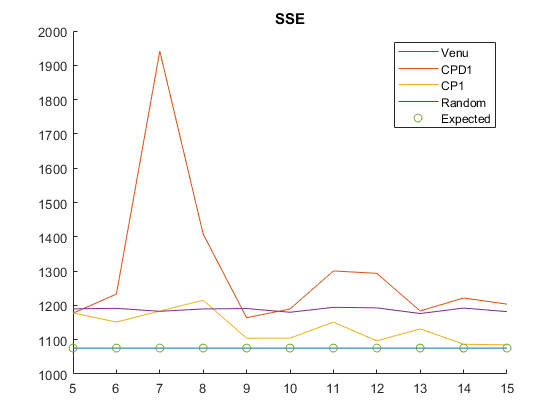

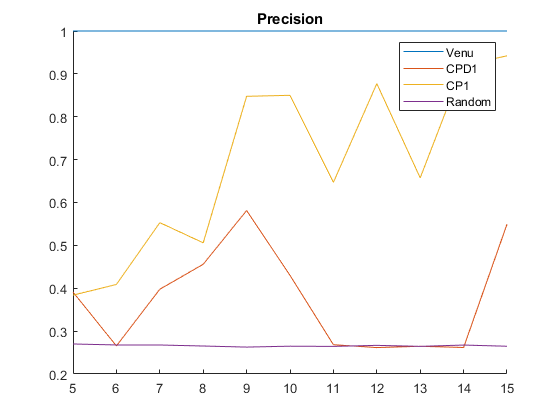

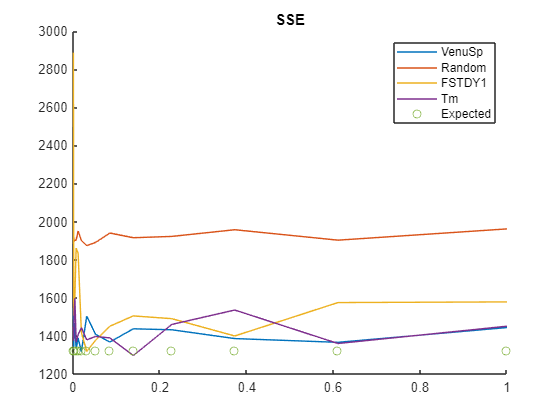

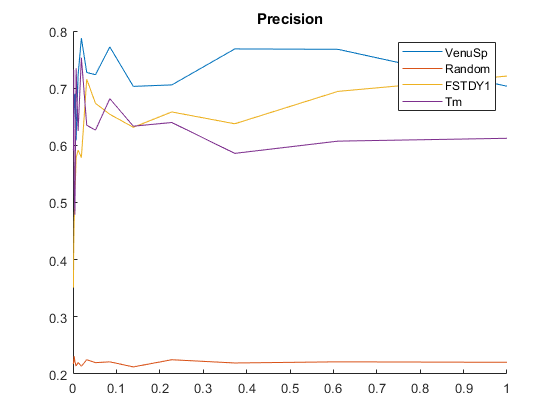

sz = [200,200,100];
% initialize;
% [R,Rp,expected] = buildRtensor(sz,5,"sigma",5);
[C,expected] = buildCTensor(sz,5,4);
methods = ["VenuSp","Random","FSTDY1","Tm"];
srange = logspace(-3,-0,15);
% Yt = sum(Yn,3);
% expected = info(2,:);
% Ct = sum(C,3);
approxTest(5,C,C,C,methods,'sinterval',srange,'expected',expected);